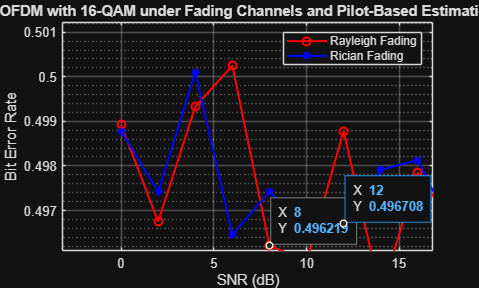

% Full MATLAB Code: OFDM Simulation with 16-QAM, Rayleigh & Rician Fading, and Pilot-based Channel Estimation

clc; clear; close all;

% Parameters
N = 64;                % Number of subcarriers
cp_len = 16;           % Cyclic prefix length
M = 16;                % 16-QAM
numSymbols = 1000;     % Number of OFDM symbols
pilot_indices = 1:4:N; % Pilot positions
pilot_value = 1 + 1i;  % Pilot symbol

SNR_dB = 0:2:20;       % SNR range
BER_rayleigh = zeros(size(SNR_dB));
BER_rician = zeros(size(SNR_dB));

for idx = 1:length(SNR_dB)
    errors_rayleigh = 0;
    errors_rician = 0;
    total_bits = 0;

    % Channel Definitions
    rayleighChan = comm.RayleighChannel( ...
        'SampleRate', 1e6, ...
        'PathDelays', [0 1e-6 2e-6], ...
        'AveragePathGains', [0 -3 -6]);

    ricianChan = comm.RicianChannel( ...
        'SampleRate', 1e6, ...
        'KFactor', 5, ...
        'PathDelays', [0 1e-6 2e-6], ...
        'AveragePathGains', [0 -2 -4]);

    for symIdx = 1:numSymbols
        % Data Generation
        bits = randi([0 1], N*log2(M), 1);
        data_bits = bits; % Save original bits before pilot insertion

        % Modulation
        symbols = qammod(bi2de(reshape(bits, [], log2(M))), M, 'UnitAveragePower', true);

        % Insert Pilots
        symbols(pilot_indices) = pilot_value;

        % IFFT
        ifft_sig = ifft(symbols, N);

        % Add Cyclic Prefix
        tx = [ifft_sig(end-cp_len+1:end); ifft_sig];

        % Rayleigh Channel
        faded_rayleigh = rayleighChan(tx);
        rx_rayleigh = awgn(faded_rayleigh, SNR_dB(idx), 'measured');

        % Rician Channel
        faded_rician = ricianChan(tx);
        rx_rician = awgn(faded_rician, SNR_dB(idx), 'measured');

        % Receiver (Same for both)
        % Remove CP
        rx_noCP_rayleigh = rx_rayleigh(cp_len+1:end);
        rx_noCP_rician = rx_rician(cp_len+1:end);

        % FFT
        rx_freq_rayleigh = fft(rx_noCP_rayleigh, N);
        rx_freq_rician = fft(rx_noCP_rician, N);

        % Channel Estimation (Pilot Based)
        H_est_rayleigh = rx_freq_rayleigh(pilot_indices) ./ pilot_value;
        H_est_rician = rx_freq_rician(pilot_indices) ./ pilot_value;

        H_interp_rayleigh = interp1(pilot_indices, H_est_rayleigh, 1:N, 'linear', 'extrap');
        H_interp_rician = interp1(pilot_indices, H_est_rician, 1:N, 'linear', 'extrap');

        % Equalization
        eq_rayleigh = rx_freq_rayleigh ./ H_interp_rayleigh.';
        eq_rician = rx_freq_rician ./ H_interp_rician.';

        % Remove pilot symbols before demod
        eq_rayleigh(pilot_indices) = [];
        eq_rician(pilot_indices) = [];

        % Demodulation
        rx_bits_rayleigh = de2bi(qamdemod(eq_rayleigh, M, 'UnitAveragePower', true), log2(M));
        rx_bits_rician = de2bi(qamdemod(eq_rician, M, 'UnitAveragePower', true), log2(M));

        % Convert to bit vector
        rx_bits_rayleigh = reshape(rx_bits_rayleigh.', [], 1);
        rx_bits_rician = reshape(rx_bits_rician.', [], 1);

        % Remove pilot bits from TX
        pilot_bits = length(pilot_indices) * log2(M);
        tx_bits = data_bits(1:end - pilot_bits);

        % Match lengths
        rx_bits_rayleigh = rx_bits_rayleigh(1:length(tx_bits));
        rx_bits_rician = rx_bits_rician(1:length(tx_bits));

        % Count errors
        errors_rayleigh = errors_rayleigh + sum(rx_bits_rayleigh ~= tx_bits);
        errors_rician = errors_rician + sum(rx_bits_rician ~= tx_bits);
        total_bits = total_bits + length(tx_bits);
    end

    BER_rayleigh(idx) = errors_rayleigh / total_bits;
    BER_rician(idx) = errors_rician / total_bits;
end

% Plot Results
figure;
semilogy(SNR_dB, BER_rayleigh, 'r-o', 'LineWidth', 1.5); hold on;
semilogy(SNR_dB, BER_rician, 'b-*', 'LineWidth', 1.5);
xlabel('SNR (dB)'); ylabel('Bit Error Rate');
legend('Rayleigh Fading', 'Rician Fading');
title('OFDM with 16-QAM under Fading Channels and Pilot-Based Estimation');
grid on;